1. Loading Dataset

The custom network trains on 128-by-128 RGB images.

The pretrained networks train on 256-by-256 RGB images.

sampleRate = 61.44e6;     % Hz
numSubFrames = 40;        % corresponds to 40 ms
frameDuration = numSubFrames*1e-3;    % seconds
trainDirRoot = fullfile(pwd,"TrainingData");
classNames = ["Noise" "NR" "LTE" "Unknown"];
trainDir = fullfile(trainDirRoot,'256x256'); 
imageSize = [256 256];
folders = trainDir;
folders = [folders,fullfile(trainDir,"captured")];
imds = imageDatastore(folders,FileExtensions=".png");

2. Loading Pixel Dataset

numClasses = length(classNames);
pixelLabelID = floor((0:numClasses-1)/(numClasses-1)*255);
pxdsTruthLTENR = pixelLabelDatastore(folders,classNames,pixelLabelID,...
                                  FileExtensions=".hdf");

3. Analyze Dataset Statistics

To see the distribution of class labels in the training dataset, use the [`countEachLabel`](docid:vision_ref#mw_1c600e69-1a15-4538-9629-7bceaafbd4e7) function to count the number of pixels by class label, and plot the pixel counts by class.

Ideally, all classes would have an equal number of observations. However, with wireless signals it is common for the classes in the training set to be imbalanced. 5G NR signals may have larger bandwidth than LTE signals, and noise fills the background. Because the learning is biased in favor of the dominant classes, imbalance in the number of observations per class can be detrimental to the learning process. In the Balance Classes Using Class Weighting section, class weighting is used to mitigate bias caused by imbalance in the number of observations per class.

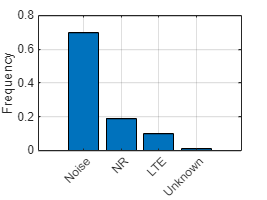

tbl = countEachLabel(pxdsTruthLTENR);
frequency = tbl.PixelCount/sum(tbl.PixelCount);
figure
bar(1:numel(classNames),frequency)
grid on
xticks(1:numel(classNames)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel("Frequency")

4. Prepare Training, Validation, and Test Sets

The deep neural network uses 80% of the signal images from the dataset for training, 10% of the images for validation, and 10% of the images for testing. The [`helperSpecSensePartitionData`](matlab:openExample('deeplearning_shared/SpectrumSensingWithDeepLearning5GLTEExample','supportingFile','helperSpecSensePartitionData')) function randomly splits the image and pixel label data into training,validation, and test sets.

[imdsTrain,pxdsTrain,imdsVal,pxdsVal,imdsTest,pxdsTest] = ...
  helperSpecSensePartitionData(imds,pxdsTruthLTENR,[80 10 10]);
cdsTrain = combine(imdsTrain,pxdsTrain);
cdsVal = combine(imdsVal,pxdsVal);
cdsTest = combine(imdsTest,pxdsTest);

cdsTrain = transform(cdsTrain, @(data)preprocessTrainingData(data,imageSize));
cdsVal = transform(cdsVal, @(data)preprocessTrainingData(data,imageSize));
cdsTest = transform(cdsTest, @(data)preprocessTrainingData(data,imageSize));

5. Use a Pretrained Network for Transfer Learning

baseNetwork = "mobilenetv2"

baseNetwork = "mobilenetv2"

layers = deeplabv3plus([256 256],numel(classNames),baseNetwork);

6. Custom Simple Semantic Segmentation Network

% inputSize = [imageSize(1) imageSize(2) 3];
% imgLayer = imageInputLayer(inputSize);
% filterSize = 3;
% numFilters = 128;
% conv = convolution2dLayer(filterSize,numFilters,'Padding',1);
% relu = reluLayer();
% poolSize = 2;
% maxPoolDownsample2x = maxPooling2dLayer(poolSize,'Stride',2);
% downsamplingLayers = [
%     conv
%     relu
%     maxPoolDownsample2x
%     conv
%     relu
%     maxPoolDownsample2x
%     conv
%     relu
%     maxPoolDownsample2x
%     conv
%     relu
%     maxPoolDownsample2x
%     ];
% filterSize = 4;
% transposedConvUpsample2x = transposedConv2dLayer(filterSize,numFilters, ...
%     'Stride',2,'Cropping',1);
% upsamplingLayers = [
%     transposedConvUpsample2x
%     relu
%     transposedConvUpsample2x
%     relu
%     transposedConvUpsample2x
%     relu
%     transposedConvUpsample2x
%     relu
%     ];
% conv1x1 = convolution2dLayer(1,numClasses);
% finalLayers = [
%     conv1x1
%     softmaxLayer()
%     ];
% layers = [
%     imgLayer    
%     downsamplingLayers
%     upsamplingLayers
%     finalLayers
%     ];

7. Balance Classes Using Class Weighting

To improve training when classes in the training set are not balanced, you can use class weighting to balance the classes. Use the pixel label counts computed earlier with the `countEachLabel` function and calculate the median frequency class weights.

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
imageFreq(isnan(imageFreq)) = [];
classWeights = median(imageFreq) ./ imageFreq;
classWeights = classWeights/(sum(classWeights)+eps(class(classWeights)));
if length(classWeights) < numClasses
    classWeights = [classWeights; zeros(numClasses-length(classWeights),1)]
end

8. Select Training Options

mbs = 40;
opts = trainingOptions("sgdm",...
  MiniBatchSize = mbs,...
  MaxEpochs = 20, ...
  LearnRateSchedule = "piecewise",...
  InitialLearnRate = 0.02,...
  LearnRateDropPeriod = 10,...
  LearnRateDropFactor = 0.1,...
  ValidationData = cdsVal,...
  ValidationPatience = 5,...
  Shuffle="every-epoch",...
  OutputNetwork = "best-validation-loss",...
  Plots = 'training-progress');

9. Train the Network

Train the network using the combined training data store, `cdsTrain`. The combined training data store contains single signal frames and true pixel labels. Use weighted cross-entropy loss together with a custom normalization to update the network during training. Define a custom loss function, lossFunction, using the [`crossentropy`](docid:nnet_ref#mw_f6eaac08-f9fa-42ae-8714-3cec2237e548) loss function and apply custom normalization. 

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:01:29         0.02                            1.9167
            1        1       00:01:30         0.02          1.9044                  


           50        2       00:18:12         0.02         0.15138           0.14831


          100        3       00:34:47         0.02        0.048232          0.053542


          150        4       00:50:32         0.02        0.045959          0.040957


          200        5       01:06:16         0.02        0.039519          0.036397
          250        6       01:21:58         0.02        0.027762          0.031746
          300        7       01:37:40         0.02        0.027021          0.032121
          350        8       01:53:19         0.02        0.016162          0.029012
          400        9       02:09:12         0.02        0.025431          0.027755
          450       10       02:25:03         0.02        0.019997          0.026726
          500       12       02:40:49        0.002        0.014918          0.026574
          550       13       02:56:30        0.002        0.017345           0.02608
          600       14       03:12:10        0.002        0.016338          0.025443
          650       15       03:27:57        0.002        0.018382          0.026218
          700       16       03:43:52        0.002        0.013939          0.027069
          750       17       03:59:39        0.002        0.01689

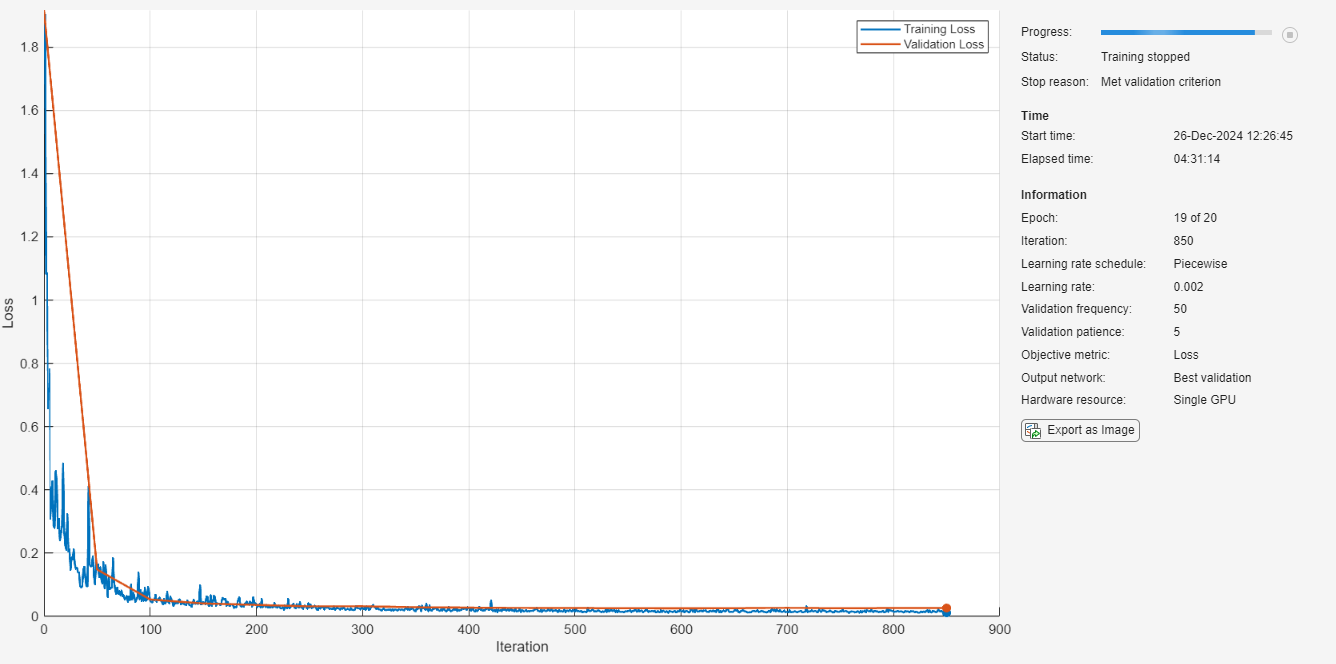

    [net,trainInfo] = trainnet(cdsTrain,layers, ...
        @(ypred,ytrue) lossFunction(ypred,ytrue,classWeights),opts);

    save(sprintf('myNet_%s_%s',"Custom", ...
        datetime('now',format='yyyy_MM_dd_HH_mm')), 'net')

10. Choose which network will be use

%Choose which network will be use
network = load('myNet_Custom_2024_12_22_03_45.mat');
net = network.net;

11. Test Deep Neural Network with Generated Data

dataDir = fullfile(trainDir,"LTE_NR");
imdsLTENR = imageDatastore(dataDir,FileExtensions=".png");
pxdsResultsLTENR = semanticseg(imdsLTENR,net,MinibatchSize=mbs,WriteLocation=tempdir, ...
    Classes=classNames);

Running semantic segmentation network
-------------------------------------
* Processed 897 images.



pxdsTruthLTENR = pixelLabelDatastore(dataDir,classNames,pixelLabelID,...
  FileExtensions=".hdf");
metrics = evaluateSemanticSegmentation(pxdsResultsLTENR,pxdsTruthLTENR);

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 897 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.82039            NaN           NaN        0.69791        0.54205  



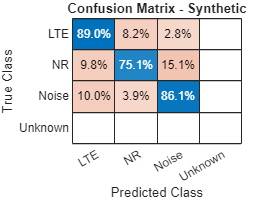

cm = confusionchart(metrics.ConfusionMatrix.Variables, ...
  classNames, Normalization='row-normalized');
cm.Title = 'Confusion Matrix - Synthetic';

12. Identify 5G NR and LTE Signals in Spectrogram

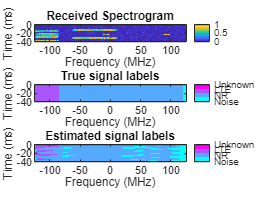

numSignals = length(imdsLTENR.Files);
idx = 14;
rcvdSpectrogram = readimage(imdsLTENR,idx);
trueLabels = readimage(pxdsTruthLTENR,idx);
predictedLabels = readimage(pxdsResultsLTENR,idx);
figure
helperSpecSenseDisplayResults(rcvdSpectrogram,trueLabels,predictedLabels, ...
  classNames,250e6,0,frameDuration)

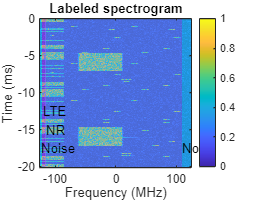

figure
helperSpecSenseDisplayIdentifiedSignals(rcvdSpectrogram,predictedLabels, ...
  classNames,250e6,0,frameDuration)

12. Test Deep Neural Network with Captured Data

capturedIdx = contains(imdsTest.Files,'captured');
imdsTestCaptured = subset(imdsTest,capturedIdx);
pxdsTestCaptured = subset(pxdsTest,capturedIdx);
pxdsResultsCaptured = semanticseg(imdsTestCaptured,net,MinibatchSize=mbs,WriteLocation=tempdir,Classes=classNames);

Running semantic segmentation network
-------------------------------------
* Processed 54 images.



metrics = evaluateSemanticSegmentation(pxdsResultsCaptured,pxdsTestCaptured);

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 54 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.98843           0.9958       0.94852      0.97848        0.96096  



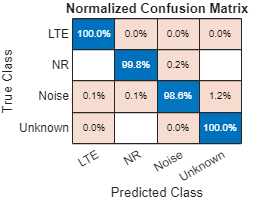

cm = confusionchart(metrics.ConfusionMatrix.Variables, ...
classNames, Normalization="row-normalized");
cm.Title = "Normalized Confusion Matrix";

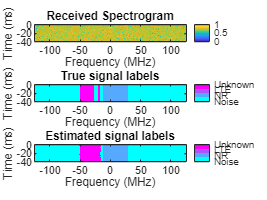

%The confusion matrix shows that the network confuses NR signals 
%with Noise or Unknown signals. Examining the captured signals reveals 
%that the captured signals with file prefix CF3550 has very low SNR and 
% the network is having a hard time to identify signals correctly. 
CF3550Indices = contains(imdsTestCaptured.Files,'CF3550');
idx = find(CF3550Indices,1);
rcvdSpectrogram = readimage(imdsTestCaptured,idx);
trueLabels = readimage(pxdsTestCaptured,idx);
predictedLabels = readimage(pxdsResultsCaptured,idx);
figure
helperSpecSenseDisplayResults(rcvdSpectrogram,trueLabels,predictedLabels, ...
classNames,250e6,0,frameDuration)

%Test with captured data but exclude CF3550 frames.
imdsTestCaptured2 = subset(imdsTestCaptured,~CF3550Indices);
pxdsTestCaptured2 = subset(pxdsTestCaptured,~CF3550Indices);
pxdsResultsCaptured2 = semanticseg(imdsTestCaptured2,net,MinibatchSize=mbs,WriteLocation=tempdir, ...
Classes=classNames);

Running semantic segmentation network
-------------------------------------
* Processed 41 images.



metrics = evaluateSemanticSegmentation(pxdsResultsCaptured2,pxdsTestCaptured2);

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 41 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.99701           0.999        0.98075      0.99417        0.99436  



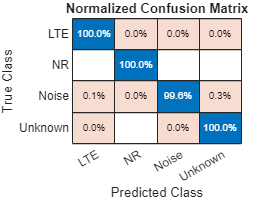

%Replot the normalized confusion matrix.
figure
cm = confusionchart(metrics.ConfusionMatrix.Variables, ...
classNames, Normalization="row-normalized");
cm.Title = "Normalized Confusion Matrix";

12. Visualize the received spectrum, true labels, and predicted labels for a captured signal.

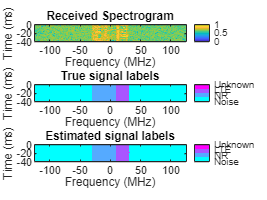

signals = find(~CF3550Indices);
numSignals = length(signals);
idx = 13;
rcvdSpectrogram = readimage(imdsTestCaptured,signals(idx));
trueLabels = readimage(pxdsTestCaptured,signals(idx));
predictedLabels = readimage(pxdsResultsCaptured,signals(idx));
figure
helperSpecSenseDisplayResults(rcvdSpectrogram,trueLabels,predictedLabels, ...
  classNames,250e6,0,frameDuration)

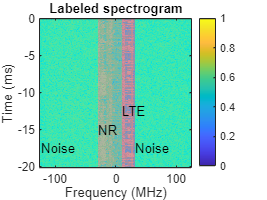

figure
helperSpecSenseDisplayIdentifiedSignals(rcvdSpectrogram,predictedLabels, ...
  classNames,250e6,0,frameDuration)

Supporting Functions

function data = preprocessTrainingData(data, imageSize)
% Resize the training image and associated pixel label image.
data{1} = imresize(data{1},imageSize);
data{2} = imresize(data{2},imageSize);
end

function loss = lossFunction(ypred,yactual,weights)
% Compute weighted cross-entropy loss.
cdim = find(dims(ypred) == 'C');
loss = crossentropy(ypred,yactual,weights,WeightsFormat="C",NormalizationFactor="none");
wn = shiftdim(weights(:)',-(cdim-2));
wnT = extractdata(yactual).*wn;
normFac = sum(wnT(:))+eps('single');
loss = loss/normFac;
end